# Distribution corrélation

## Accès dossier et choix essai

Il est nécessaire d'avoir lancé "Correlation.mat" précédement

clear;
Type = "DCC7SD";
Materiau = "4140";
Eprouvette ='3';
Numero = '1';
 
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

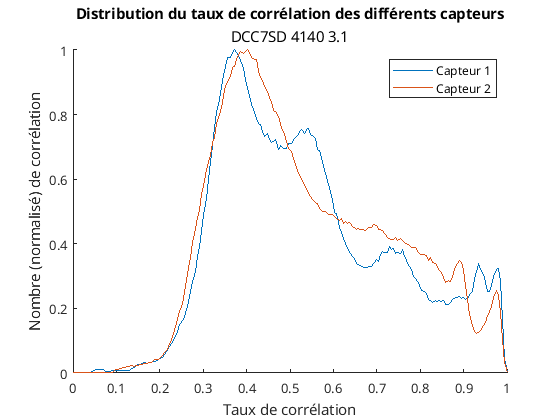

n =200;
 
Distri = cell(6,1);
for i = 1:6
    Distri{i} = zeros(1,n);
end
d = 0;
x = linspace(0,1,n);
if exist('Cor1','var')
      d = 1;
      Distri{1} = Distrib(n,Cor1);
end
if exist('Cor2','var')
      d = 2;
      Distri{2} = Distrib(n,Cor2);
end
if exist('Cor3','var')
      d = 3;
      Distri{3} = Distrib(n,Cor3);
end
if exist('Cor4','var')
      d = 4;
      Distri{4} = Distrib(n,Cor4);
end
if exist('Cor5','var')
      d = 5;
      Distri{5} = Distrib(n,Cor5);
end
if exist('Cor6','var')
      d = 6;
      Distri{6} = Distrib(n,Cor6);
end
im = figure();
hold on 
for i = 1:d
    plot(x,Distri{i},'DisplayName',strcat("Capteur ",string(i)));
end
hold off
legend();
title("Distribution du taux de corrélation des différents capteurs");
subtitle(strcat(Type," ",Materiau," ",Eprouvette,".",Numero));
xlabel("Taux de corrélation");
ylabel("Nombre (normalisé) de corrélation");

## Sauvegarde

% this part saves the big matrices Cor et dt. It's specific to my organisation
repertoire_traitees = acces_donnees_traitees();
save(strcat('/home/tdelaselle/Documents/Données_essais/Traitement_essais/',Type,'/',Materiau,'/',Naming,'.mat'),"Distri",'-append');
% save(strcat('/home/tdelaselle/Documents/Données_essais/Resultats/',Type,'/',Materiau,'/',Naming,'.png'),im);

"Sauvegardé !"

ans = "Sauvegardé !"